#  034IN "Fundamentals of Automatic Control" - Introduction to MATLAB/Simulink - Solving Exercises on MATLAB Programming

## Exercise: Scripts

### Assignment

Make a helloWorld **script**, such that

- When run, the script should display the following text

                                        `Hello World!`

                                        `I am going to learn MATLAB!`

- **Hint**: use the command `disp` to display strings. Check the command help for options and examples.

- **Hint 2**: The simplest way to write a string is to surround text with single quotes, like 

- Open the editor, create a new script, write the code and save the script as `helloWorld.m`

### Solution

% helloWorld.m
% my first hello world program in MATLAB

disp('Hello World!');
disp('I am going to learn MATLAB!');


## Exercise: Scalars and Maths Operations

### Assignment

Consider the variable


$$y(t) = \left[ 1-\displaystyle e^{-\left(\frac{t}{\tau}\right)} \right]$$


where the time constant $\tau$ is


$$\tau = 1.5 \;\text{days}$$


- Calculate the number of **seconds** in $1.5$ days and name this variable `tau`.

- Evaluate $y(t)$ when


$$\left\{ \begin{array}{lcl}
t = 0 & \Longrightarrow& y(0)=?\\
t = \frac{1}{10} & \Longrightarrow& y\left(\frac{1}{10}\right)=?\\
t=120 & \Longrightarrow& y(120) = ?\\
t = 2400 &  \Longrightarrow& y(2400)=?
\end{array} \right.
$$


- Create a script, write the code and save the script as `expRateEval1SCRIPT.m `

### Solution

% solution of Exercise: Scalars and Maths Operations
% script expRateEval1SCRIPT.m

Tau_days = 1.5;

secPerDay = 60*60*24;
tau = Tau_days * secPerDay;

% inefficient solution
t1 = 0;
y1 = (1-exp(-t1/tau));

t2 = 1/10;
y2 = (1-exp(-t2/tau));

t3 = 120;
y3 = (1-exp(-t3/tau));

t4 = 2400;
y4 = (1-exp(-t4/tau));



## Exercise: Maths and Vector Operations

### Assignment

Consider the variable


$$y(t) = \left[ 1-\displaystyle e^{-\left(\frac{t}{\tau}\right)} \right]$$


where the time constant $\tau$ is


$$\tau = 1.5 \;\text{days}$$


- Calculate the number of **seconds** in $1.5$ days and name this variable `tau`.

- Create a row-vector for the time instants


$$t = \left[ 0 \,,\; \frac{1}{10}\,,\; 120\,,\; 2400 \right]$$


- Evaluate $y(t)$ when the time $t$ assumes values in the previously defined array.

- Create a script, write the code and save the script as `expRateEval_2_SCRIPT.m `

### Solution

% solution of Exercise: Maths and Vector Operations
% script: expRateEval_2_SCRIPT.m

Tau_days = 1.5;

secPerDay = 60*60*24;
tau = Tau_days * secPerDay;

% let's define the time row array
t = [ 0, 1/10, 120, 2400];

% evaluate the function using the time row-vector
y_vals = (1-exp(-t/tau));



## Exercise: Vectors and Matrices 

### Assignment

- Create the row-vectors

$a = \left[ 1 \quad 2 \right] \qquad \Longleftrightarrow$   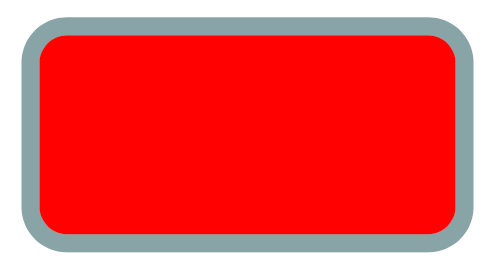

$b = \left[ 3 \quad 4 \right] \qquad \Longleftrightarrow$    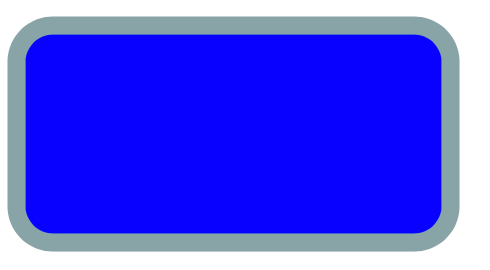

- Create the column-vector

$c = \left[\begin{array}{c}  5 \\6 \end{array} \right] \qquad \Longleftrightarrow$    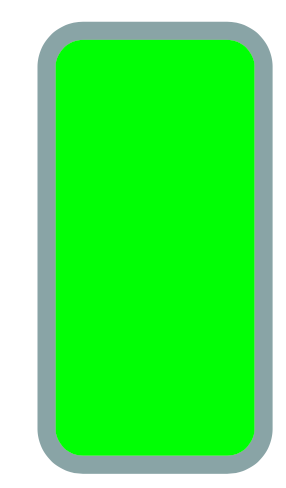

- By concatenating vectors or matrices according to the following pictures, create the new matrices $D$, $E$ and $F$

$D \qquad \Longleftrightarrow$                            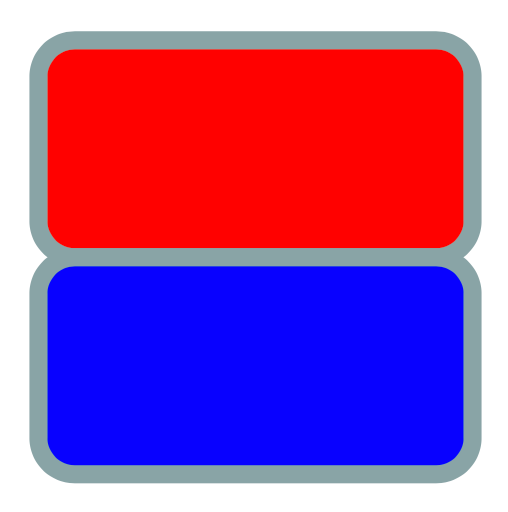

$E \qquad \Longleftrightarrow$                    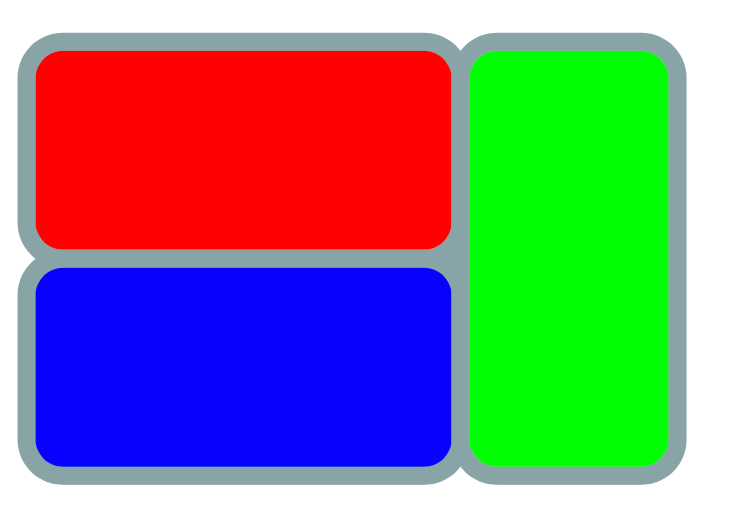

$F \qquad \Longleftrightarrow$      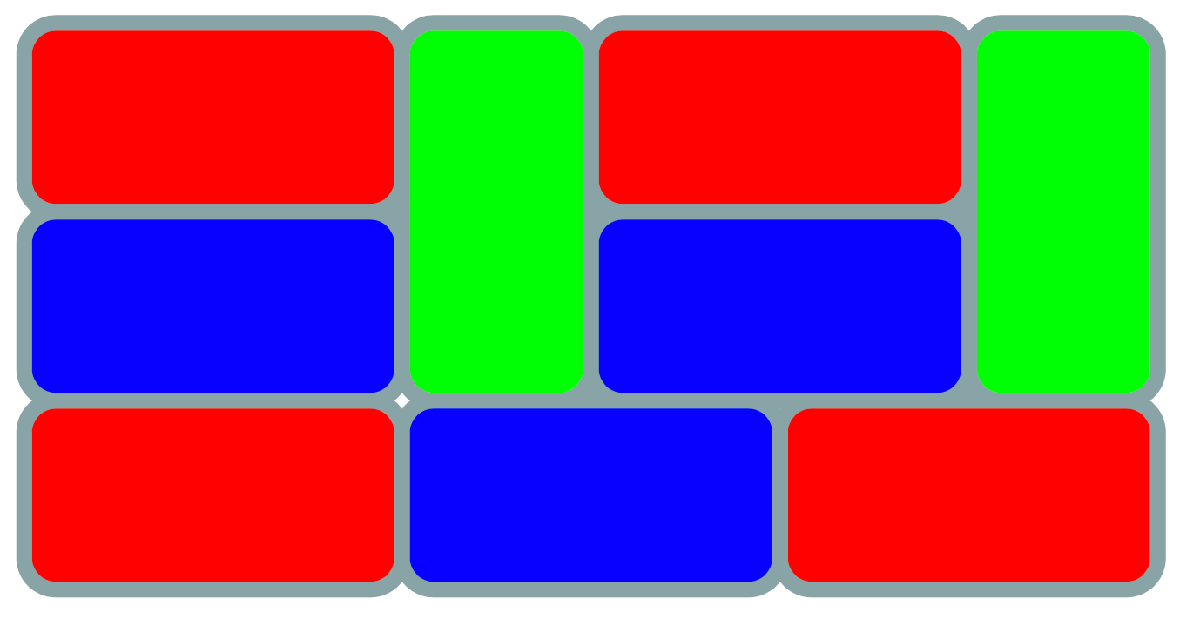

- Save the vectors $a,\,b,\,c$ and the matrices $D,\,E,\,F$ to a file named `ExConcatenateMatrices.mat `

- **Hint**: use the command `save`

- Create a script, write the code and save the script as `exConcatenateVectors_SCRIPT.m `

### Solution

% exConcatenateVectors_SCRIPT.m

a = [1 2];
b = [3 4];

c = [ 5; ...
      6 ];

D = [ a ; ...
      b  ]

E = [D c ]
% equivalent expression:
% E_equiv = [ [ a ; b] c]

F = [ [E E]; [a b a]]
% equivalent expression ? 

save ExConcatenateMatrices a b c D E F 
% refer to the save command documentation

## Exercise: Vector Math Operations

### Assignment

Consider the variable


$$y(t) = \left[ 1-\displaystyle e^{-\left(\frac{t}{\tau}\right)} \right]$$


where the time constant $\tau$ is


$$\tau = 1.5 \;\text{days}$$


- Create a row-vector `tVec` that has $10000$ samples  between $0$ and $648000$ seconds.

- **Hint**: use the command `linspace`. Do you know any alternative to this command?

- Evaluate $y(t)$ for each of the time instant $t$ in `tVec`.

- Create a script, write the code and save the script as `expRateEval_3_SCRIPT.m `

### Solution

% solution of Exercise: Vector Math Operations
% script: expRateEval_3_SCRIPT.m

clear % clean the MATLAB workspace
Tau_days = 1.5;

secPerDay = 60*60*24;
tau = Tau_days * secPerDay;

% let's define the time row array tVec
startT = 0;
endT = 648000; 
Nsamples = 10000;

tVec = linspace(startT, endT, Nsamples);

% evaluate the function using the time row-vector
y_vals = (1-exp(-tVec/tau));
